# Laboratory 8

## Exercise 0

clear;

clear Workspace variables

clc;

clear Command Window

A = [1 2 3;4 5 6]

A =      1     2     3
     4     5     6


declare and define matrix `A`

size(A)

ans =      2     3


return size of matrix `A` as a matrix `[rows columns]`

sA = size(A)

sA =      2     3


declare variable sA and define it as size matrix of A

[rows columns] = size(A)

rows = 2

columns = 3

sAr=size(A,1)

sAr = 2

sAc=size(A,2)

sAc = 3

## Exercise 1

%y1 (x) = x ^ 2 + 1
%y2 (x) = x ^ 3 + x ^ 2 + x + 1
%for x <-5, 5>,
clear all; close all;
t = -5:0.01:5;
y1 = t.^2 +1;
y2 = t.^3 + t.^2 + t +1;
y1_indexes = 1:1:size(y1,2);
figure (2);
plot (y1, 'r.');
hold on;
plot (y1, 'r-');
plot (y1_indexes, y1, 'b*');

title ('Title of the chart, e.g. y_1 plotted with two types of tags')
xlabel ('X-axis')
ylabel ('Y-axis')
grid on;
legend('y1', 'y2', 'y3')

figure (3);
plot(y1, 'b');
plot(y2, 'r');

## Exercise 2

%% main
clear all; close all; clc;

step = 0.01;
x = -5:step:5;
Y1 = 0*x;
Y2 = 0*x;

for i=1:size(x, 2)
    [y1, y2] = exercise3_function1(x(i));
    Y1(i) = y1;
    Y2(i) = y2;
end
 figure(1);
 subplot(2, 1, 1);
 plot(x, Y1, x, Y2);
 title('Ex1 graph');
 xlabel ('X-axis')
 ylabel ('Y-axis')
 legend('y1', 'y2');
 grid on;
 subplot(2, 1, 2);
 plot(x, Y1, x, Y2);
 title('Ex2 graph');
 xlabel ('X-axis')
 ylabel ('Y-axis')
 legend('y1', 'y2');
 grid on;

## Exercise 2a

clear all; close all; clc;

figure(4);
step = 0.1;
T = -5:step:5;
[Y1, Y2] = exercise2a_function(T);
subplot(2, 1, 1);
plot(T, Y1, T, Y2);

Y1 = 0*T;
Y2 = 0*T;
for i=1:size(T, 2)
    [y1, y2] = exercise2_function1(T(i));
    Y1(i) = y1;
    Y2(i) = y2;
end
subplot(2, 1, 2);
plot(T, Y1, T, Y2);

## Exercise 2b

%y1 (x) = x ^ 2 + 1
%y2 (x) = x ^ 3 + x ^ 2 + x + 1
%for x <-5, 5>,
clear all; close all; clc;

p1 = [1 0 1];
p2 = [1 1 1 1];
step = 0.01;
T = -5:step:5;

Y1 = polyval(p1, T);
Y2 = polyval(p2, T);

plot(T, Y1, T, Y2);

## Exercise 3

clear all; close all; clc;
load('lab_8.mat');
if size(Y1, 2) > 0 & size(Y1, 1) > 0 & size(T, 2) > 0 
    disp('correctly imported variables')
end

correctly imported variables


## Exercise 4

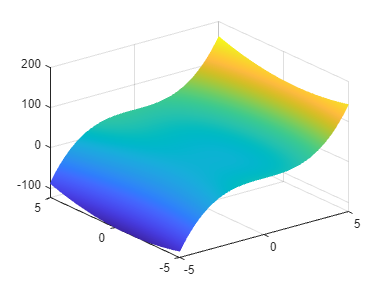

clear all; close all; clc;
step = 0.01;
X = -5:step:5;
Y = -5:step:5;
[Z] = exercise4_function(X, Y);
% surf(X, Y, Z);
mesh(X, Y, Z);
print('mesh.png','-dpng')

`mesh.png`

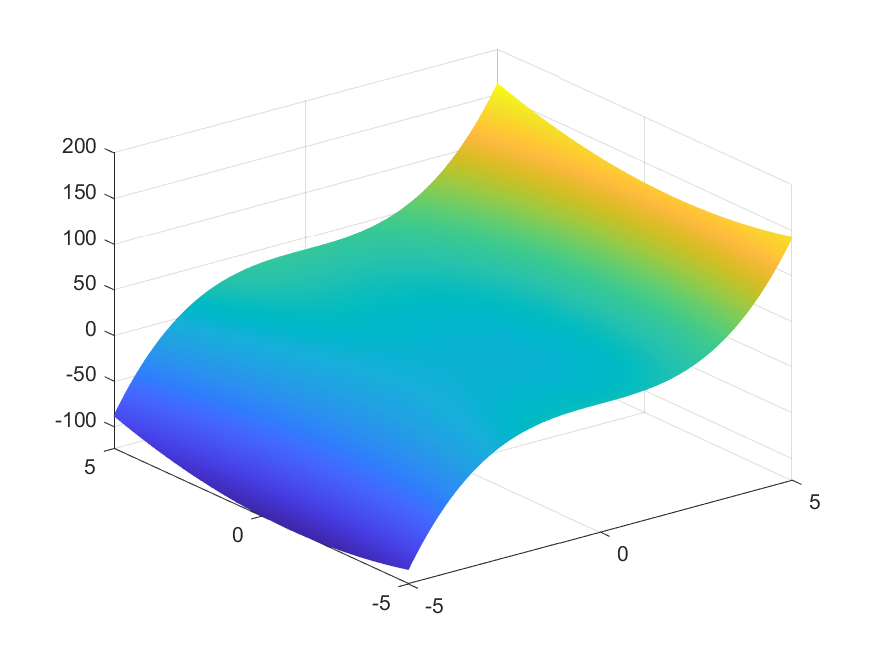

function [Y1,Y2] = exercise2a_function(T)
Y1 = T.^2 +1;
Y2 = T.^3 + T.^2 + T +1;
end

function [y1,y2] = exercise3_function1(t)
y1 = t.^2 +1;
y2 = t.^3 + t.^2 + t +1;
end
